## **Introduction to space Geodesy (WinSem 24/25):**

## **Assignment 2: Date, time, and frequency**

- **Awsam Agbaria (0501833) - awsam.agbaria@campus.tu-berlin.de**

- **Tarik Abu Mukh (0501953) - abumukht@campus.tu-berlin.de**

- **Francesco Cherubini (0515856) - francesco.cherubini@campus.tu-berlin.de**

- **Zilong Liu (0501297) -  zilong.liu@campus.tu-berlin.de**

- **Mathimenaka Ramasamy (0501301) - mathimenaka.ramasamy@campus.tu-berlin.de**

### Question 1 testing:

% Testing the rotation matrices
axes = [1, 2, 3]; % Define the axes

for ax = axes
    % Compute the rotation matrix for a full rotation (2*pi) about the current axis
    R1 = rot3d(2*pi, ax);  
    
    % Display the rotation matrix
    fprintf('Rotation Matrix a of 2pi angle about axis=%d, expected identity matrix, actual matrix\n', ax);
    disp(R1);
end

Rotation Matrix a of 2pi angle about axis=1, expected identity matrix, actual matrix


    1.0000         0         0
         0    1.0000    0.0000
         0   -0.0000    1.0000



Rotation Matrix a of 2pi angle about axis=2, expected identity matrix, actual matrix


    1.0000         0    0.0000
         0    1.0000         0
   -0.0000         0    1.0000



Rotation Matrix a of 2pi angle about axis=3, expected identity matrix, actual matrix


    1.0000   -0.0000         0
    0.0000    1.0000         0
         0         0    1.0000




for ax = axes
    % Compute the rotation matrix for a full rotation (2*pi) about the current axis
    R1 = rot3d(0, ax);  
    
    % Display the rotation matrix
    fprintf('Rotation Matrix of a 0-angle rotationa about axis=%d, expected identity matrix, actual matrix\n', ax);
    disp(R1*R1);
end

Rotation Matrix of a 0-angle rotationa about axis=1, expected identity matrix, actual matrix


     1     0     0
     0     1     0
     0     0     1



Rotation Matrix of a 0-angle rotationa about axis=2, expected identity matrix, actual matrix


     1     0     0
     0     1     0
     0     0     1



Rotation Matrix of a 0-angle rotationa about axis=3, expected identity matrix, actual matrix


     1     0     0
     0     1     0
     0     0     1




for ax = axes
    % Compute the rotation matrix for a full rotation (2*pi) about the current axis
    R1 = rot3d(pi, ax);  
    
    % Display the rotation matrix
    fprintf('Rotation Matrix of two consecutive pi-angle rotations about axis=%d, expected identity matrix, actual matrix\n', ax);
    disp(R1*R1);
end

Rotation Matrix of two consecutive pi-angle rotations about axis=1, expected identity matrix, actual matrix


    1.0000         0         0
         0    1.0000    0.0000
         0   -0.0000    1.0000



Rotation Matrix of two consecutive pi-angle rotations about axis=2, expected identity matrix, actual matrix


    1.0000         0    0.0000
         0    1.0000         0
   -0.0000         0    1.0000



Rotation Matrix of two consecutive pi-angle rotations about axis=3, expected identity matrix, actual matrix


    1.0000   -0.0000         0
    0.0000    1.0000         0
         0         0    1.0000






disp(['The rotation is clockwise.']);

The rotation is clockwise.


### Question 2 testing:

% Testing the reflection matrices
M1 = mir3d(1);  % Reflection about the x-axis
M2 = mir3d(2);  % Reflection about the y-axis
M3 = mir3d(3);  % Reflection about the z-axis
M1M1=M1*M1;
M2M2=M2*M2;
M3M3=M3*M3;
M1M2M3=M1*M2*M3;
% Display reflection matrices with explanations
disp('Reflection Matrix M1: Reflection about the x-axis');

Reflection Matrix M1: Reflection about the x-axis


disp(M1);

    -1     0     0
     0     1     0
     0     0     1




disp('Reflection Matrix M2: Reflection about the y-axis');

Reflection Matrix M2: Reflection about the y-axis


disp(M2);

     1     0     0
     0    -1     0
     0     0     1




disp('Reflection Matrix M3: Reflection about the z-axis');

Reflection Matrix M3: Reflection about the z-axis


disp(M3);

     1     0     0
     0     1     0
     0     0    -1




fprintf('Multiplication of reflection matrix with itself:\n'); 

Multiplication of reflection matrix with itself:


disp(M1M1);

     1     0     0
     0     1     0
     0     0     1



disp(M2M2);

     1     0     0
     0     1     0
     0     0     1



disp(M3M3);

     1     0     0
     0     1     0
     0     0     1



fprintf('Multiplication of matrices M1,M2,M3:\n');

Multiplication of matrices M1,M2,M3:


disp(M1M2M3);

    -1     0     0
     0    -1     0
     0     0    -1



### Question 3 testing:

- Lets start by calling our iterative method and showing the difference between eccentric anomaly and mean anomaly

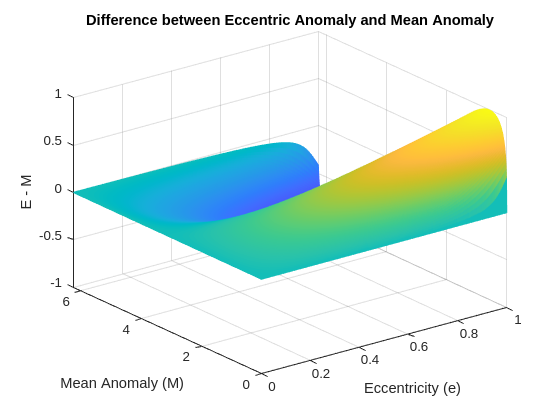

M_values = 0:0.01:2*pi-0.01;  
e_values = 0:0.001:0.999;
E_minus_M = zeros(length(M_values), length(e_values));  
iterations = zeros(length(M_values), length(e_values));  
tol = 10^-6;   
max_iter = 1000;
for i = 1:length(M_values)
    for j = 1:length(e_values)
        initial_guess = M_values(i);          
        [E_an, i_ter] = kepler(M_values(i), e_values(j), tol, max_iter, initial_guess); 
        E_minus_M(i,j) = E_an - M_values(i); 
        iterations(i,j) = i_ter;              
    end
end

figure;
mesh(e_values, M_values, E_minus_M); 
xlabel('Eccentricity (e)');
ylabel('Mean Anomaly (M)');
zlabel('E - M');
title('Difference between Eccentric Anomaly and Mean Anomaly');

- We can visualize our iteration method we computed:

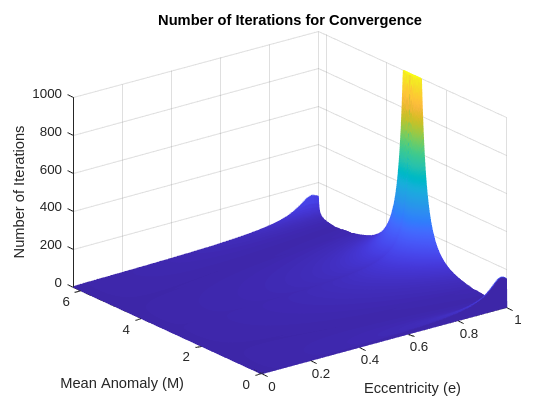

figure;
mesh(e_values, M_values, iterations);
xlabel('Eccentricity (e)');
ylabel('Mean Anomaly (M)');
zlabel('Number of Iterations');
title('Number of Iterations for Convergence');

- Lets show where anomalies differ maximally and where they differ minimally

[max_diff, max_diff_idx] = max(E_minus_M(:));
[min_diff, min_diff_idx] = min(E_minus_M(:));
[max_iter_val, max_iter_idx] = max(iterations(:));
[min_iter_val, min_iter_idx] = min(iterations(:));
median_iterations = median(iterations(:));

[M_max_diff_idx, e_max_diff_idx] = ind2sub(size(E_minus_M), max_diff_idx);
[M_min_diff_idx, e_min_diff_idx] = ind2sub(size(E_minus_M), min_diff_idx);
[M_max_iter_idx, e_max_iter_idx] = ind2sub(size(iterations), max_iter_idx);
[M_min_iter_idx, e_min_iter_idx] = ind2sub(size(iterations), min_iter_idx);

fprintf('\n--- Analysis Summary ---\n');


--- Analysis Summary ---


fprintf('1. An additional input argument (initial guess for E) improves convergence.\n');

1. An additional input argument (initial guess for E) improves convergence.


fprintf('2. Maximal difference between E and M occurs at M = %.4f and e = %.4f.\n', ...
        M_values(M_max_diff_idx), e_values(e_max_diff_idx));

2. Maximal difference between E and M occurs at M = 0.5700 and e = 0.9990.


fprintf('3. Minimal difference between E and M occurs at M = %.4f and e = %.4f.\n', ...
        M_values(M_min_diff_idx), e_values(e_min_diff_idx));

3. Minimal difference between E and M occurs at M = 5.7100 and e = 0.9990.


fprintf('4. Maximal iterations required at M = %.4f and e = %.4f, with %d iterations.\n', ...
        M_values(M_max_iter_idx), e_values(e_max_iter_idx), max_iter_val);

4. Maximal iterations required at M = 3.0400 and e = 0.9900, with 1000 iterations.


fprintf('5. Minimal iterations required at M = %.4f and e = %.4f, with %d iterations.\n', ...
        M_values(M_min_iter_idx), e_values(e_min_iter_idx), min_iter_val);

5. Minimal iterations required at M = 0.0000 and e = 0.0000, with 1 iterations.


fprintf('6. Median number of iterations for convergence is %.2f.\n', median_iterations);

6. Median number of iterations for convergence is 11.00.


### Question 4 testing:

The function can convert properly the hour and minute part if the input is an hour angle (expressed as decimal number), while seconds need to be converted into decimal seconds. To do this, the code line sec = (remainder - min) * 60;  needs to be replaced by sec = (remainder - min); so that decimal seconds are returned.

[deg, min, sec] = deg2dms(60.743);

angleDegree = 60.7430

disp('Conversion of 60.743 in DMS: ');

Conversion of 60.743 in DMS: 


% Display result
fprintf('ERA: %d° %d\'' %d"\n', deg, min, sec);

ERA: 60° 44' 3.480000e+01"



bacwkard_conversion = dms2deg(deg, min, sec);
disp('Backward conversion from DMS to decimal degree, expected result 60.743, actual result:');

Backward conversion from DMS to decimal degree, expected result 60.743, actual result:


disp(bacwkard_conversion);

   60.7430




%negative example
[deg, min, sec] = deg2dms(-60.743);

angleDegree = 60.7430

disp('Conversion of -60.743 in DMS: ');

Conversion of -60.743 in DMS: 


% Display result
fprintf('ERA: %d° %d\'' %d"\n', deg, min, sec);

ERA: -60° 44' 3.480000e+01"



bacwkard_conversion = dms2deg(deg, min, sec);
disp('Backward conversion from DMS to decimal degree, expected result -60.743, actual result:');

Backward conversion from DMS to decimal degree, expected result -60.743, actual result:


disp(bacwkard_conversion);

  -60.7430




%negative example
[deg, min, sec] = deg2dms(-0.743);

angleDegree = 0.7430

disp('Conversion of -0.743 in DMS: ');

Conversion of -0.743 in DMS: 


% Display result
fprintf('ERA: %d° %d\'' %d"\n', deg, min, sec);

ERA: 0° -44' 3.480000e+01"



bacwkard_conversion = dms2deg(deg, min, sec);
disp('Backward conversion from DMS to decimal degree, expected result -0.743, actual result:');

Backward conversion from DMS to decimal degree, expected result -0.743, actual result:


disp(bacwkard_conversion);

   -0.7430



### Question 5 testing:

format long g
function Fx = F(x) 
Fx = x - fix(x); 

2024-10-20 is CEST!


end

UTC="2024-10-20,00:00:00"



disp('2024-10-20 is CEST!');
disp('UTC="2024-10-20,00:00:00"');

UTC = [2024, 12, 1, 12, 0, 0];
dUT1_ms = 0.0535314; 

UT1_seconds = UTC(6) + dUT1_ms;
UT1 = UTC;
UT1(6) = UT1_seconds; 

UTC Time:


        2024          12           1          12           0           0



[UT1_JD, UT1_MJD] = gre2jd(UT1(1), UT1(2), UT1(3), UT1(4), UT1(5), UT1(6));

UT1 Time:


disp('UTC Time:');

                      2024                        12                         1                        12                         0                 0.0535314



disp(UTC);

UT1 Julian Date:


disp('UT1 Time:');

          2460646.00000062



disp(UT1);

UT1 Modified Julian Date:


disp('UT1 Julian Date:');

          60645.5000006198



disp(UT1_JD);
disp('UT1 Modified Julian Date:');
disp(UT1_MJD);

% a
T = UT1_JD - 2451545.0; 
ERA = 2*pi*(0.7790572732640+1.00273781191135448*T);

angleDegree =           250.518275998067


ERA=rad2deg(ERA);
ERA=mod(ERA,360);

ERA: 250° 31' 6"


[deg,minutes, seconds]=deg2dms(ERA);
% Display result
fprintf('ERA: %d° %d\'' %d"\n', deg, minutes, round(seconds, 0));

%b
t=(UT1_JD-2451545.0)/36525;
GMST=(F(UT1_JD)*86400+24110.54841-86400/2+8640184.812866*t+0.093104*t*t-6.2e-6*t*t*t)/3600;
GMST = mod(GMST, 24);

delta_psi=0.001096;
theta=(84381.448-46.8150*t-5.9*10e-4*(t^2)+1.813*10e-3*(t^3))*pi/648000;
omega=(450160.28-482890.539*t+7.455*(t^2)+0.008*(t^3))*pi/648000+2*pi*F(-5*t);
Eq_e=delta_psi*cos(theta)+(2.64*10e-3*sin(omega)+6.3*10e-5*sin(2*omega))*pi/648000;
Eq_e=Eq_e.*12/pi;


angleDegree =           250.518275998067


GAST=GMST+Eq_e;
GAST = mod(GAST, 24);

GST: 250 h 31 m 5.793593e+00 s


[deg,minutes,seconds]=deg2dms(ERA);

fprintf('GST: %02d h %02d m %02d s\n', deg, minutes, seconds);

### Question 6 testing:

- Westford – Wettzell baseline is about 6000 km in ITRF.

- a 20ms VLBI group delay at 2024-10-20, 02:00:00 CET (TT)

- Compute difference of delay in TT vs TCB by converting TT into TCG and TCG into TCB

format long
% Constants
tt_delay = 20e-3;
c = 299792458;


The baseline delay in TCG is:


tcg_delay = TT_to_TCG(tt_delay);

   0.020000000013939



disp("The baseline delay in TCG is:")

Which makes the difference between TT and TCG delay:


disp(tcg_delay)

     1.393857945730659e-11



disp("Which makes the difference between TT and TCG delay:")
disp(abs(tt_delay-tcg_delay))

The baseline time difference in TCB is:


tcb_Delay = TCG_to_TCB(tcg_delay);

   0.020000197585642



disp("The baseline time difference in TCB is:")

Which makes the difference between TCG and TCB delay:


disp(tcb_Delay)

     1.975717031296731e-07



disp("Which makes the difference between TCG and TCB delay:")

and the difference between TT and TCB is:


disp(abs(tcg_delay-tcb_Delay))

     1.975856417091304e-07



disp("and the difference between TT and TCB is:")
disp(abs(tcb_Delay-tt_delay))

Lets convert this delay difference between TT and TCB into meters:


59.2346851935 (m)

disp("Lets convert this delay difference between TT and TCB into meters:")
fprintf("%.10f (m)",abs(tcb_Delay-tt_delay)*299792458)

- Now Lets see out of all the solar system bodies taken into account, which ones contribute the most into computing the general relativistic transformation

% Constants
AU = 149597870.7;

body_names = ["Sun", "Mercury", "Venus", "Moon", "Mars", "Ceres", "Jupiter", "Saturn", "Uranus",...
              "Neptune", "Pluto", "Eris"];

grav_terms = [1.32712440018e20, 2.2032e13, 3.24859e14, 4.9048695e12, 4.282837e13, ...
              6.26325e10, 1.26686534e17, 3.7931187e16, 5.793939e15, 6.836529e15, ...
              8.71e11, 1.108e12];

m_dist_to_earth = [AU, 91691000, 41400000, 385000.6, 78340000, 414000000, 628730000, ...
                   1275000000, 2723950000, 4351400000, 5890000000, 96.1*AU];
% Computing contributions and sorting them
contribution = grav_terms./m_dist_to_earth;
sorted_contribution = sort(contribution,'descend');
V_ext = sum(grav_terms./m_dist_to_earth);
cont_sum=0;
indices = {};
sampling = true;

% GOing through one element at a time and checking the % of the actual
% value, we add all the biggest elements that add up to >99.99%
for element = sorted_contribution
    cont_sum = cont_sum + element;
    index = find(contribution==element);

    fprintf('%s : %10.5f \n',body_names(index), element);

    if sampling==true
        indices{end+1} = body_names(index);
    end

    fprintf('We have reached %.10f contribution', cont_sum/V_ext);

    if abs(V_ext-cont_sum) < 0.001*V_ext
        sampling = false;
    end


Sun : 887127867509.14636 


We have reached 0.9997111532 contribution

Jupiter : 201495926.70940 


We have reached 0.9999382205 contribution

Saturn : 29749950.58824 


We have reached 0.9999717459 contribution

Moon : 12739900.92483 


We have reached 0.9999861026 contribution

Venus : 7846835.74879 


We have reached 0.9999949452 contribution

Uranus : 2127035.73854 


We have reached 0.9999973422 contribution

Neptune : 1571110.21740 


We have reached 0.9999991127 contribution

Mars : 546698.62139 


We have reached 0.9999997288 contribution

Mercury : 240285.30608 


We have reached 0.9999999996 contribution

Ceres :  151.28623 


We have reached 0.9999999997 contribution

Pluto :  147.87776 


We have reached 0.9999999999 contribution

Eris :   77.07099 


We have reached 1.0000000000 contribution

end


The solar system bodies needed for up to 99.99/100 accuracy are:

fprintf('The solar system bodies needed for up to 99.99/100 accuracy are:')

    {["Sun"]}



disp(indices)

- Lets compare between Special relativistic term $\frac{v^2 }{2}$ and the general gravitational term $\sum_{A\not= e} \frac{{\textrm{GM}}_A }{|x_e -x_A |}$

% Bc_velocity^2 / 2
spec_term = 30e3^2/2;
% GM / r
grav_term = 398600.435507/6.371e6;
% This does not show that its twice as large, therefore I calculated the
% gravitational wrong.
fprintf("General /  Spec = %.10f", grav_term/spec_term)

General /  Spec = 0.0000000001

fprintf("Spec /  General = %.10f", spec_term/grav_term)

Spec /  General = 7192541062.7145490646